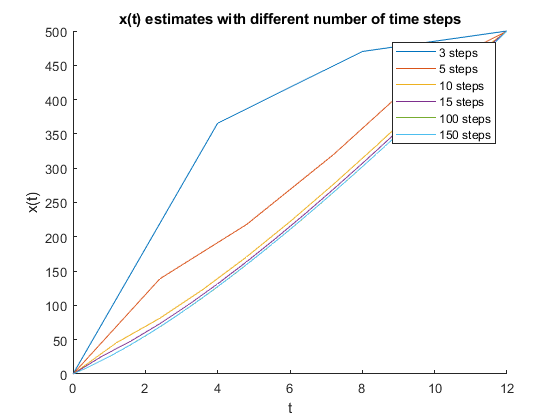

%boundary value problem solver
c = 12.5;
m = 70;
g = 9.81;
x_0 = 0;
x_12 = 500;
[y3,t3] = bvpsolver(3,c,m,g,x_0,x_12);
[y5,t5] = bvpsolver(5,c,m,g,x_0,x_12);
[y10,t10] = bvpsolver(10,c,m,g,x_0,x_12);
[y15,t15]= bvpsolver(15,c,m,g,x_0,x_12);
[y100,t100]= bvpsolver(100,c,m,g,x_0,x_12);
[y150,t150]= bvpsolver(150,c,m,g,x_0,x_12);
hold on
plot(t3,y3,'DisplayName','3 steps')
plot(t5,y5,'DisplayName','5 steps')
plot(t10,y10,'DisplayName','10 steps')
plot(t15,y15,'DisplayName','15 steps')
plot(t100,y100,'DisplayName','100 steps')
plot(t150,y150,'DisplayName','150 steps')
legend('show')
xlabel('t')
ylabel('x(t)')
title('x(t) estimates with different number of time steps')

%at n=15, the increasing of n results in small change in x(t), so n = 10
%gives a fairly good estimate, as well as being very fast
%approx 125 metres


function [y,t] = bvpsolver(n,c,m,g,x_0,x_12)
dt = 12/n;
centerdiag = zeros(n-1,1) + (-2+c/m*dt);
leftdiag = zeros(n-2,1) + (1-c/m*dt);
rightdiag = zeros(n-2,1) + 1;
A = diag(centerdiag,0) + diag(leftdiag,-1) + diag(rightdiag,1);
b = [-x_0*(1-c/m*dt);zeros(n-3,1)+g*dt^2;-x_12*(1)];
y = [x_0;A\b;x_12];
t = (0:dt:12)';
end